# Create Deep Learning Network Architecture

Script for creating the layers for a deep learning network with:

Run the script to create the layers in the workspace variable `layers`.

To learn more, see [Generate MATLAB Code From Deep Network Designer](matlab:helpview('deeplearning','generate_matlab_code')).

Auto-generated by MATLAB on 07:26

## Create the Array of Layers

vgg16Net = [
    imageInputLayer([32 32 3],"Name","input")
    convolution2dLayer([3 3],64,"Name","conv1_1","Padding",[1 1 1 1],"WeightL2Factor",0)
    reluLayer("Name","relu1_1")
    convolution2dLayer([3 3],64,"Name","conv1_2","Padding",[1 1 1 1],"WeightL2Factor",0)
    reluLayer("Name","relu1_2")
    maxPooling2dLayer([2 2],"Name","pool1","Stride",[2 2])
    convolution2dLayer([3 3],128,"Name","conv2_1","Padding",[1 1 1 1],"WeightL2Factor",0)
    reluLayer("Name","relu2_1")
    convolution2dLayer([3 3],128,"Name","conv2_2","Padding",[1 1 1 1],"WeightL2Factor",0)
    reluLayer("Name","relu2_2")
    maxPooling2dLayer([2 2],"Name","pool2","Stride",[2 2])
    convolution2dLayer([3 3],256,"Name","conv3_1","Padding",[1 1 1 1],"WeightL2Factor",0)
    reluLayer("Name","relu3_1")
    convolution2dLayer([3 3],256,"Name","conv3_2","Padding",[1 1 1 1],"WeightL2Factor",0)
    reluLayer("Name","relu3_2")
    convolution2dLayer([3 3],256,"Name","conv3_3","Padding",[1 1 1 1],"WeightL2Factor",0)
    reluLayer("Name","relu3_3")
    maxPooling2dLayer([2 2],"Name","pool3","Stride",[2 2])
    convolution2dLayer([3 3],512,"Name","conv4_1","Padding",[1 1 1 1],"WeightL2Factor",0)
    reluLayer("Name","relu4_1")
    convolution2dLayer([3 3],512,"Name","conv4_2","Padding",[1 1 1 1],"WeightL2Factor",0)
    reluLayer("Name","relu4_2")
    convolution2dLayer([3 3],512,"Name","conv4_3","Padding",[1 1 1 1],"WeightL2Factor",0)
    reluLayer("Name","relu4_3")
    maxPooling2dLayer([2 2],"Name","pool4","Stride",[2 2])
    convolution2dLayer([3 3],512,"Name","conv5_1","Padding",[1 1 1 1],"WeightL2Factor",0)
    reluLayer("Name","relu5_1")
    convolution2dLayer([3 3],512,"Name","conv5_2","Padding",[1 1 1 1],"WeightL2Factor",0)
    reluLayer("Name","relu5_2")
    convolution2dLayer([3 3],512,"Name","conv5_3","Padding",[1 1 1 1],"WeightL2Factor",0)
    reluLayer("Name","relu5_3")
    maxPooling2dLayer([2 2],"Name","pool5","Stride",[2 2])
    fullyConnectedLayer(4096,"Name","fc6","WeightL2Factor",0)
    reluLayer("Name","relu6")
    dropoutLayer(0.5,"Name","drop6")
    fullyConnectedLayer(4096,"Name","fc7","WeightL2Factor",0)
    reluLayer("Name","relu7")
    dropoutLayer(0.5,"Name","drop7")
    fullyConnectedLayer(1000,"Name","fc8_1","WeightL2Factor",0)
    fullyConnectedLayer(1,"Name","fc8_2","WeightL2Factor",0)
    regressionLayer("Name","regressionoutput")];

## Plot the Layers

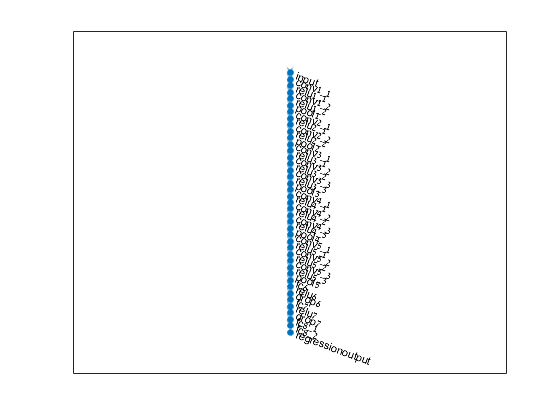

plot(layerGraph(vgg16Net));